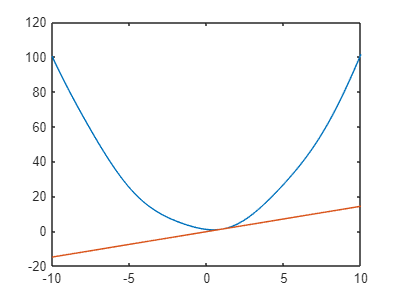

syms x;
f = power(x, 2) - sin(x) + 1;
f1 = diff(f);

% y = f(a) + f'(a) * (x-a)
a = 1;
p1 = vpa(subs(f, x, a));
p2 = vpa(subs(f1, x, a));

t1 = @(q) power(q, 2) - sin(q) + 1;
t2 = @(q) p1 + p2 * (q - a);

x = linspace(-10, 10, 1000);
y1 = t1(x);
y2 = t2(x);

plot(x, y1, x, y2)